# SeqNMFE sandbox: Jisu Sleep Seq Analyses

close all
restoredefaultpath
global PARAMS  % these are global parameters that can be called into any function.  I limit these to directories for storing, loading, and saving files and codebases.
os = computer;

if ismac
    PARAMS.data_dir = '/Users/jericcarmichael/Documents/Williams_Lab/2019-12-04_11-10-01_537day0base1'; % where to find the raw data
    PARAMS.inter_dir = '/Users/jericcarmichael/Documents/Williams_Lab/Temp/'; % where to put intermediate files
    PARAMS.stats_dir = '/Users/jericcarmichael/Documents/Williams_Lab/Stats/'; % where to put the statistical output .txt
    PARAMS.code_base_dir = '/Users/jericcarmichael/Documents/GitHub/vandermeerlab/code-matlab/shared'; % where the codebase repo can be found
    PARAMS.code_CEH2_dir = '/Users/jericcarmichael/Documents/GitHub/CEH2'; % where the multisite repo can be found
    
elseif strcmp(os, 'GLNXA64')
    
    %     PARAMS.data_dir = '/home/ecarmichael/Documents/Williams_Lab/2019-12-04_11-10-01_537day0base1'; % where to find the raw data
    PARAMS.data_dir = '/home/ecarmichael/Documents/Williams_Lab/Raw_data/JC/7_12_2019_PV1069_LTD5'; % where to find the raw data
    %     PARAMS.raw_data_dir = '/home/ecarmichael/Documents/Williams_Lab/Raw_data/EV/';
    PARAMS.raw_data_dir = '/home/ecarmichael/Documents/Williams_Lab/Raw_data/JC/'; % raw data location.
    PARAMS.inter_dir = '/home/ecarmichael/Documents/Williams_Lab/Temp/'; % where to put intermediate files
    PARAMS.stats_dir = '/home/ecarmichael/Documents/Williams_Lab/Stats/'; % where to put the statistical output .txt
    PARAMS.code_base_dir = '/home/ecarmichael/Documents/GitHub/vandermeerlab/code-matlab/shared'; % where the codebase repo can be found
    PARAMS.code_CEH2_dir = '/home/ecarmichael/Documents/GitHub/CEH2'; % where the multisite repo can be found
    
else
    PARAMS.data_dir = 'D:\Dropbox (Williams Lab)\Williams Lab Team Folder\Eva\Processed place'; % where to find the raw data
    PARAMS.raw_data_dir = 'D:\Dropbox (Williams Lab)\Jisoo\Upload\pv1002'; % raw data location.
    PARAMS.inter_dir = 'D:\Dropbox (Williams Lab)\Jisoo\Upload\pv1002\Inter'; % where to put intermediate files
    PARAMS.stats_dir = 'D:\Dropbox (Williams Lab)\Jisoo\Upload\pv1002\Inter\Stats'; % where to put the statistical output .txt
    PARAMS.code_base_dir = 'C:\Users\ecarm\Documents\GitHub\vandermeerlab\code-matlab\shared'; % where the codebase repo can be found
    PARAMS.code_CEH2_dir = 'C:\Users\ecarm\Documents\GitHub\CEH2'; % where the multisite repo can be found
    PARAMS.code_seqnmf_dir = 'C:\Users\ecarm\Documents\GitHub\seqNMF'; % where the multisite repo can be found
    
end

rng(11,'twister') % for reproducibility

% add the required code
addpath(genpath(PARAMS.code_base_dir));
addpath(genpath(PARAMS.code_CEH2_dir));
cd(PARAMS.raw_data_dir) % move to the data folder

clear d os

## load a nice session

% this_sess = 'D:\Dropbox (Williams Lab)\Jisoo\Upload\pv1002\3_26_2019';
% this_sess = 'D:\Dropbox (Williams Lab)\Jisoo\Upload\pv1043\6_11_2019_PV1043_LTD1\LTD1'
% this_sess = 'D:\Dropbox (Williams Lab)\Jisoo\JisooProject2020\RawData\pv1043\6_15_2019_PV1043_LTD5\H13_M30_S2_LTD5';
% this_sess = 'D:\Dropbox (Williams Lab)\Jisoo\JisooProject2020\RawData\pv1043\6_13_2019_PV1043_LTD3\H13_M18_S10_LTD3';
this_sess = 'D:\Dropbox (Williams Lab)\Jisoo\JisooProject2020\RawData\pv1060\11_23_2019_PV1060_HATD5\H13_M25_S1_HATD5';
dir_parts = strsplit(this_sess, filesep);
subject = dir_parts{end-2};
session = dir_parts{end-1};

% processed data dir
% cd('D:\Dropbox (Williams Lab)\Jisoo\JisooProject2020\2020_Results_aftercutting\4.PlaceCell\pv1043\LTD5');
% cd('D:\Dropbox (Williams Lab)\Jisoo\JisooProject2020\2020_Results_aftercutting\4.PlaceCell\pv1043\LTD3');
this_process_dir ='D:\Dropbox (Williams Lab)\Jisoo\JisooProject2020\2020_Results_aftercutting\2.Selective_cell';

% REM file dir
this_rem_dir = ['D:\Dropbox (Williams Lab)\Jisoo\JisooProject2020\2020_Results_aftercutting\Across_episodes\Inter' filesep upper(subject) filesep session];



% load the main data
cd(this_sess);

warning off  % otherwise you get all the videoencoder warnings.
load('ms.mat');
% clearvars -except ms this_sess PARAMS  % some ms files saved all the other variables as well.  not sure why.
load('behav.mat');
if exist('AllSpatialFiringData.mat', 'file')
    load('AllSpatialFiringData.mat')
    fprintf('No AllSpatialFiringData.mat found.  Can''t distinguish place cells\n')
end

if ~isfield(ms, 'Binary')
    fprintf('No binary field found in ms, extracting...\n')
    ms = MS_msExtractBinary_detrendTraces(ms, 2);
end

No binary field found in ms, extracting...


MS_msExtractBinary_detrendTraces:  User specified Z-score = 2
MS_msExtractBinary_detrendTraces:  Infered sampling rate = 30 Hz



% use another place cell classification file

cd(this_process_dir)

if contains(this_sess, 'HAT')
    sess_name = strsplit(session, '_');
    S = dir(fullfile(this_process_dir,[lower(sess_name{end-1}) '_' sess_name{end} '*cell.mat']));
    load(fullfile(this_process_dir,S.name));
        fprintf('Using a HAT session. Loading cell file: %s\n', S.name);
else
    load("spatial_analysis.mat")
    load("spatial_analysis_classif.mat")
    fprintf('Using Processed spatial info file ''spatial_analyses_classif.mat''\n')
end

Error using load
'spatial_analysis.mat' is not found in the current folder or on the MATLAB path, but exists in:
    D:\Dropbox (Williams Lab)\Jisoo\JisooProject2020\RawData\pv1060\11_23_2019_PV1060_HATD5\H13_M25_S1_HATD5

Change the MATLAB current folder or add its folder to the MATLAB path.

## plug it into SeqNMF

addpath(PARAMS.code_seqnmf_dir)
Fs =mode(diff(ms.time));

% data_in = ms.FiltTraces';
data_in = ms.Binary';

pos(:,1) = interp1(behav.time,behav.position(:,1),ms.time);
pos(:,2) = interp1(behav.time,behav.position(:,2),ms.time);
velocity = interp1(behav.time, behav.speed, ms.time);


% remove inactive cells
% total_act = sum(data_in,2);

% keep_idx = total_act>30; % exclude cells that are active for less than 1s total

% data_in = data_in(keep_idx,:);

% sort data based on place field location

% centroids = [];
% for iC = length(spatial_analysis.bin):-1:1
%     if iscell(spatial_analysis.bin{iC,1}.PlaceFieldCentroid)
%         temp = cell2mat(spatial_analysis.bin{iC,1}.PlaceFieldCentroid);
%     else
%         temp = spatial_analysis.bin{iC,1}.PlaceFieldCentroid;
%     end
%     centroids(iC) = temp(1);
%
%     % is it a place cell?
%     Place_Cell_D1(iC) = spatial_analysis.bin{iC,1}.IsPlaceCell;
%
%     place_map_1d(iC,:) = mean(spatial_analysis.bin{iC,1}.PlaceField,1)/max(mean(spatial_analysis.bin{iC,1}.PlaceField,1)); % get the 1d place field and normalize.
% end

% limit to predefined anxiety cells.
keep_idx = ([AnxietyCell_Out.Left_Selective, AnxietyCell_Out.Right_Selective]);
keep_idx(isnan(keep_idx)) = [];
keep_idx = sort(keep_idx);
data_in = data_in(keep_idx,:);

% sort the centroids (1D only)
%     centroids = centroids(Place_Cell_D1);
%
% [~,sort_idx] = sort(centroids);
%
% place_map_1d = place_map_1d(Place_Cell_D1,:);
% place_map_1d = place_map_1d(sort_idx,:);
%
% imagesc(place_map_1d);
% axis xy

% data_in = data_in(sort_idx,:);

% %% run the normalizing steps from SeqNMFE paper: Since seqNMF would
% % prioritize the neurons with the most power, we renormalized by dividing
% % the signal from each neuron by the sum of the maximum value of that row
% % and the 95th percentile of the signal across all neurons. In this way,
% % neurons with larger peaks were given some priority, but not much more
% % than that of neurons with weaker signals.
%
% p_95 = prctile(data_in, 95, 'all');
% for iC = size(data_in, 1):-1:1
%    data_in(iC,:) =  (data_in(iC,:) / sum(data_in(iC,:)))/p_95;
%    data_in(iC,:) = data_in(iC,:) + abs(min(data_in(iC,:)));
%
% end

## limit to laps

movement_thresh = 2.5; % in cm/s
movement_idx = velocity >movement_thresh; % get times when the animal was moving.

left_idx = MS_get_direction(pos(:,1), -.1); % use -threshold for leftbound and + for right.
right_idx = MS_get_direction(pos(:,1), .1); % use -threshold for leftbound and + for right.

left_idx = left_idx & movement_idx; % only keep the indices when they are moving to the left.
right_idx = right_idx & movement_idx;

[L_laps, L_lap_start_idx, L_lap_end_idx] = MS_get_laps(left_idx, floor(1.5*(Fs)),floor(10*(Fs)));
[R_laps, R_lap_start_idx, R_lap_end_idx] = MS_get_laps(right_idx, floor(1.5*(Fs)),floor(10*(Fs)));

% make L and R lap only data sets.
L_data = data_in(:,L_laps > 0);
R_data = data_in(:,R_laps > 0);

## for plotting get the position during laps.

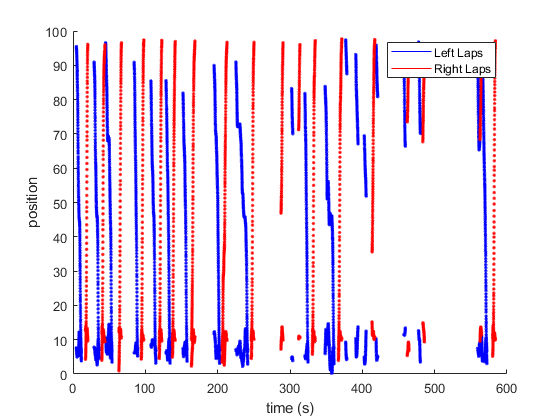

L_laps_pos = pos(L_laps > 0,:);
L_laps_time = ms.time(L_laps >0,:);

R_laps_pos = pos(R_laps > 0,:);
R_laps_time = ms.time(R_laps >0,:);

figure(111)
hold on
% plot(ms.time, pos, 'color', [.2 .2 .2])
plot(L_laps_time/1000, nan(length(L_laps_pos),1), 'b')
plot(R_laps_time/1000, nan(length(R_laps_pos),1), 'r')

plot(L_laps_time/1000, L_laps_pos, '.b')
plot(R_laps_time/1000, R_laps_pos, '.r')
xlabel('time (s)')
ylabel('position')
legend({'Left Laps', 'Right Laps'})

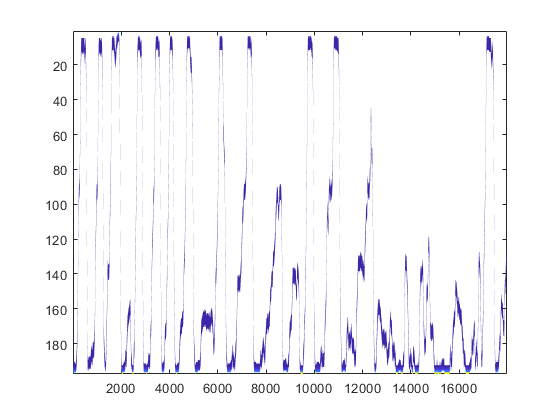


% split the velocity values
L_velo = []; R_velo = [];
for iL = 1:length(L_lap_start_idx)
    L_velo = [L_velo; velocity(L_lap_start_idx(iL):L_lap_end_idx(iL))];% append the velocity values for each R lap
end
for iL = 1:length(R_lap_start_idx)
    R_velo = [R_velo; velocity(R_lap_start_idx(iL):R_lap_end_idx(iL))]; % append the velocity values for each R lap
end

% convert trajectory to 3d mat as place x time x logical (was the animal here) for plotting
% in the SeqNMFe WHPlot function
p_range = floor(min(L_laps_pos(:,1),[], 'all')):0.5:ceil(max(L_laps_pos,[],'all')); % make a range of positions which the middle value here being the precision (default 0.5cm)
L_pos_mat = [];
for iP = length(L_laps_pos):-1:1
    pos_idx= nearest_idx3(L_laps_pos(iP), p_range);
    pos_val = zeros(size(p_range));   % hack to have zeros in all the other positions.
    pos_val(pos_idx) = 1;
    %     pos_val(pos_idx) = L_velo(iP);
    L_pos_mat(iP,:) = smooth(pos_val,10); % fill in the y axis with zeros for unoccupied and 1 for occupied.
end

p_range = floor(min(R_laps_pos(:,1),[], 'all')):0.5:ceil(max(R_laps_pos,[],'all')); % make a range of positions which the middle value here being the precision (default 0.5cm)
R_pos_mat = [];
for iP = length(R_laps_pos):-1:1
    pos_idx= nearest_idx3(R_laps_pos(iP), p_range);
    pos_val = zeros(size(p_range));   % hack to have zeros in all the other positions.
    %     pos_val(pos_idx) = R_velo(iP);
    pos_val(pos_idx) = 1;
    R_pos_mat(iP,:) = smooth(pos_val,10); % fill in the y axis with zeros for unoccupied and 1 for occupied.
end

% make a position x time matrix for plotting
p_range - floor(min(pos, [], 'all')) : 0.5: ceil(max(pos,[],'all'));
pos_mat = [];
for iP = length(pos):-1:1
    if isnan(pos(iP))
        pos_mat(iP,:) = zeros(size(p_range));
    else
        pos_idx= nearest_idx3(pos(iP), p_range);
        pos_val = zeros(size(p_range));   % hack to have zeros in all the other positions.
        %     pos_val(pos_idx) = R_velo(iP);
        pos_val(pos_idx) = 1;
        pos_mat(iP,:) = smooth(pos_val,10); % fill in the y axis with zeros for unoccupied and 1 for occupied.
    end
end
pos_mat= pos_mat';
figure;
plot_pos_mat = pos_mat;
plot_pos_mat(plot_pos_mat == 0) =NaN;
nan_imagesc_ec(plot_pos_mat);
set(gca, 'color', 'w')

## Fit with seqNMF: most of this is straight out of Mackevicius et al. 2019 [https://elifesciences.org/articles/38471](https://elifesciences.org/articles/38471)

% this_data = data_in; % which data to use.
this_data = R_data;
this_pos = R_pos_mat';
% this_pos = pos_mat;

PosFs = Fs; % b/c we already interpolated the position data to the ms.time.

% break data into training set and test set
splitN = floor(size(this_data,2)*.75);
splitS = floor(size(this_pos,2)*.75);

% make the test/trian sets.
trainNEURAL = this_data(:,1:splitN);
trainPOS = this_pos(:,1:splitS);
testNEURAL = this_data(:,(splitN+1):end);
testPOS = this_pos(:,(splitS+1):end);

% Set some parameters
rng(235); % fixed rng seed for reproduceability
X = trainNEURAL;
figure
K = 3;
L = 10;
Lneural = ceil(L*Fs);

## Procedure for choosing lambda

nLambdas = 30; % increase if you're patient
K = 3;
X = trainNEURAL;

Unrecognized function or variable 'trainNEURAL'.

lambdas = sort([logspace(-2,-4,nLambdas)], 'ascend');
loadings = [];
regularization = [];
cost = [];
    [N,T] = size(X);
    
parfor li = 1:length(lambdas)
    [W, H, ~,loadings(li,:),~]= seqNMF(X,'K',K,'L',Lneural,...
        'lambdaL1W', .1, 'lambda', lambdas(li), 'maxiter', 100, 'showPlot', 0);
    [cost(li),regularization(li),~] = helper.get_seqNMF_cost(X,W,H);
    display(['Testing lambda ' num2str(li) '/' num2str(length(lambdas))])
end

## plot Lambda cost

windowSize = 3;
b = (1/windowSize)*ones(1,windowSize);
a = 1;
Rs = filtfilt(b,a,regularization);
minRs = prctile(regularization,10); maxRs= prctile(regularization,90);
Rs = (Rs-minRs)/(maxRs-minRs);
R = (regularization-minRs)/(maxRs-minRs);
Cs = filtfilt(b,a,cost);
minCs =  prctile(cost,10); maxCs =  prctile(cost,90);
Cs = (Cs -minCs)/(maxCs-minCs);
C = (cost -minCs)/(maxCs-minCs);

figure; hold on
plot(lambdas,Rs, 'b')
plot(lambdas,Cs,'r')
scatter(lambdas, R, 'b', 'markerfacecolor', 'flat');
scatter(lambdas, C, 'r', 'markerfacecolor', 'flat');
xlabel('Lambda'); ylabel('Cost (au)')
set(legend('Correlation cost', 'Reconstruction cost'), 'Box', 'on')
set(gca, 'xscale', 'log', 'ytick', [], 'color', 'none')
set(gca,'color','none','tickdir','out','ticklength', [0.025, 0.025])
shg

% get the lambda point after the cross point.
lambda_diff = Rs - Cs;
idx = find(lambda_diff < 0);

best_lambda = lambdas(idx(1));



## Events based version

lambda = 0.001;% from the above.  "Go just above the cross point"
fprintf('\n*************** Events based ***************\n')


*************** Events based ***************



% event based
lambdaOrthoH = .1; % favor events-based (these can take any value, don't need to be zero and one)
lambdaOrthoW = 0;
fprintf('Running seqNMF...K = %d  L = %d sec\n', K, L)

Running seqNMF...K = 3  L = 10 sec


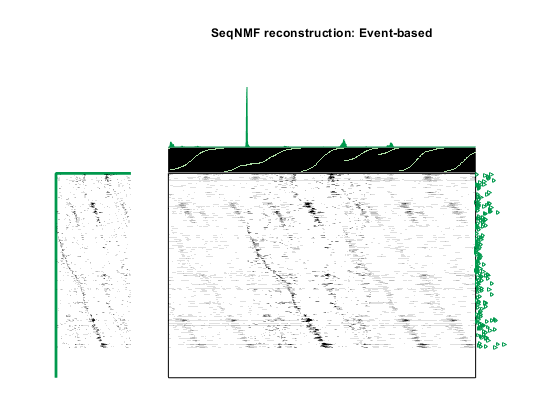

[W_e, H_e, ~,loadings,power]= seqNMF(X,'K',K,'L',Lneural,...
    'lambdaL1W', .1, 'lambda', lambda, 'maxiter', 100, 'showPlot', 1,...
    'lambdaOrthoH', lambdaOrthoH, 'lambdaOrthoW', lambdaOrthoW);


% test if any are significant
p = .05; % desired p value for factors

disp('Testing significance of factors on held-out data')
[pvals,is_significant] = test_significance(testNEURAL,W_e,p);

W_e = W_e(:,is_significant,:);
H_e = H_e(is_significant,:);
fprintf('Events-based: Found %d/%d significant factors\n', sum(is_significant), length(is_significant))


## Plot events based results

[max_factor, L_sort, max_sort, hybrid] = helper.ClusterByFactor(W_e(:,:,:),1);
indSort = hybrid(:,3);
tstart = 1; % plot data starting at this timebin
figure;
WHPlot(W_e(indSort,:,:),H_e(:,tstart:end), X(indSort,tstart:end), ...
    0,trainPOS(:,floor(tstart*Fs/PosFs):end))
title('Significant seqNMF factors, with raw data: Event-based')

figure;
WHPlot(W_e(indSort,:,:),H_e(:,tstart:end), ...
    helper.reconstruct(W_e(indSort,:,:),H_e(:,tstart:end)),...
    0,trainPOS(:,floor(tstart*Fs/PosFs):end))
title('SeqNMF reconstruction: Event-based')


## Parts based version

fprintf('\n*************** Parts based ***************\n')


*************** Parts based ***************


%parts based
lambdaOrthoH = 0;
lambdaOrthoW = 1;
fprintf('Running seqNMF...K = %d  L = %d sec\n', K, L)

Running seqNMF...K = 3  L = 10 sec


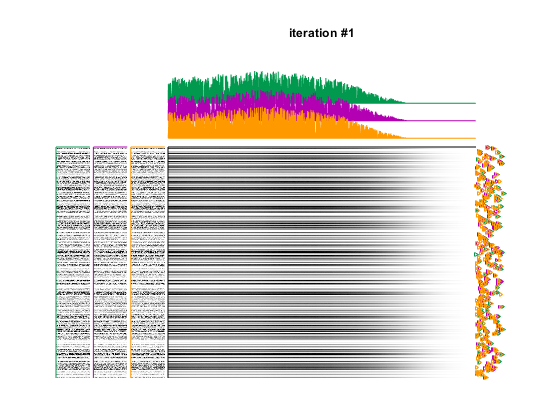

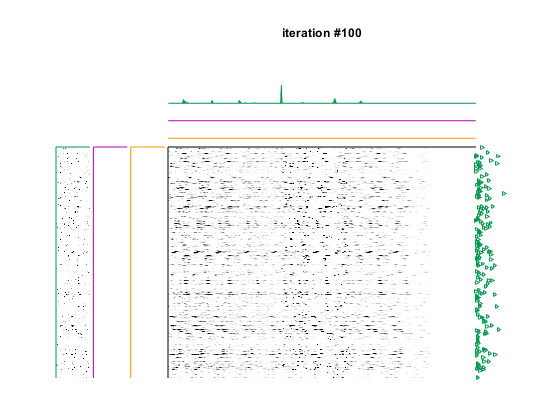

[W_p, H_p, ~,loadings,power]= seqNMF(X,'K',K,'L',Lneural,...
    'lambdaL1W', .1, 'lambda', lambda, 'maxiter', 100, 'showPlot', 1,...
    'lambdaOrthoH', lambdaOrthoH, 'lambdaOrthoW', lambdaOrthoW);


% test if any are significant
p = .05; % desired p value for factors

disp('Testing significance of factors on held-out data')

Testing significance of factors on held-out data


[pvals,is_significant] = test_significance(testNEURAL,W_p,p);

W_p = W_p(:,is_significant,:);
H_p = H_p(is_significant,:);
fprintf('Found %d/%d significant factors\n', sum(is_significant), length(is_significant))

Found 1/3 significant factors


### Plot the parts based results

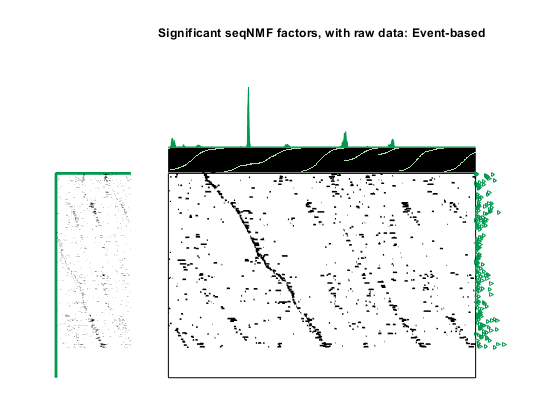

[max_factor, L_sort, max_sort, hybrid] = helper.ClusterByFactor(W_e(:,:,:),1);
indSort = hybrid(:,3);
tstart = 1; % plot data starting at this timebin
WHPlot(W_p(indSort,:,:),H_p(:,tstart:end), X(indSort,tstart:end), ...
    0,trainPOS(:,floor(tstart*Fs/PosFs):end))
title('Significant seqNMF factors, with raw data: Event-based')

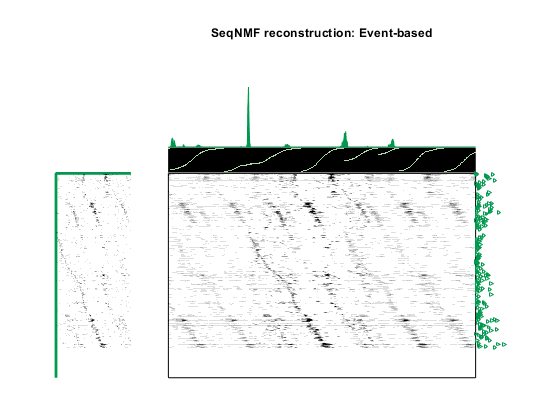


WHPlot(W_p(indSort,:,:),H_p(:,tstart:end), ...
    helper.reconstruct(W_p(indSort,:,:),H_p(:,tstart:end)),...
    0,trainPOS(:,floor(tstart*Fs/PosFs):end))
title('SeqNMF reconstruction: Event-based')

## plot a reconstruction of the W matrix for sanity

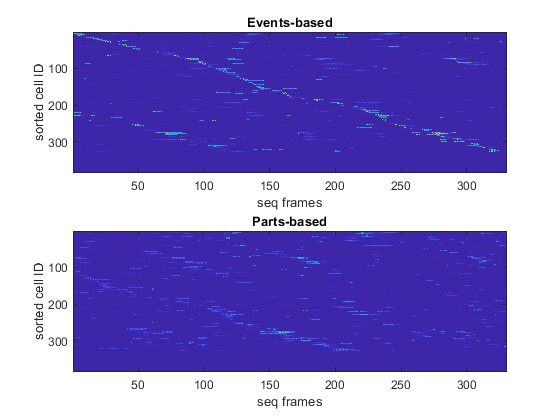

figure;
subplot(2,1,1)
% offset = 10^-1; % offset for each cell
this_seq = squeeze(W_e(indSort,:,:));
imagesc(this_seq);
ylabel('sorted cell ID')
xlabel('seq frames')
title('Events-based')


subplot(2,1,2)
% offset = 10^-1; % offset for each cell
this_seq = squeeze(W_p(indSort,:,:));
imagesc(this_seq);
ylabel('sorted cell ID')
xlabel('seq frames');
title('Parts-based')



% axis xy

% this_seq(this_seq <= 0.05) = NaN;
% for iT = size(this_seq,1):-1:1
%     plot(0:size(this_seq,3)-1,squeeze(this_seq(iT,:,:))-offset*iT)
%
% end



## Save any significant sequences

All_Seq = [];
All_Seq.subject = subject;
All_Seq.session = session;
All_Seq.task = dir_parts{end}(end-3:end);
All_Seq.Sig_seq = is_significant;
All_Seq.cfg.K = K;
All_Seq.cfg.L = L;
All_Seq.cfg.lambda = lambda;
% All_Seq.


## Get some REM data for this session


cd(this_rem_dir)

% load the concatenated sleep data.
load('all_binary_post_REM.mat');
load('all_binary_post_SW.mat');

% restrict, transpose and rename the sleep types.
REM_data = all_binary_post_REM(:,keep_idx)';

SW_data = all_binary_post_SW(:,keep_idx)';

clear all_binary*


## run Seq on REM and look for significant sequences using the same K and lambda from the task.

Running seqNMF...K = 3  L = 2 sec


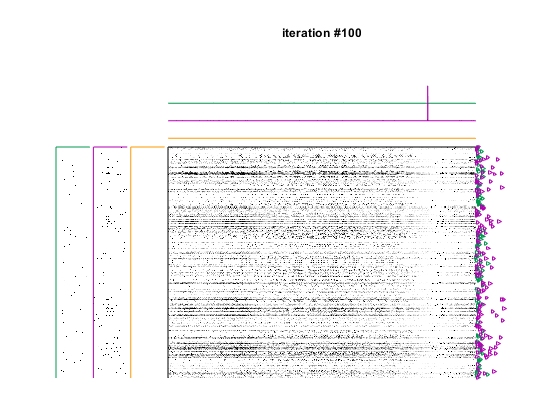

Testing significance of factors on held-out data


Found 1/3 significant factors


Running seqNMF...K = 3  L = 4 sec


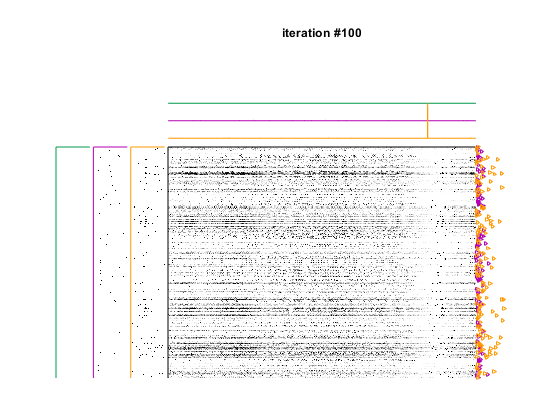

Testing significance of factors on held-out data


Found 1/3 significant factors


Running seqNMF...K = 3  L = 6 sec


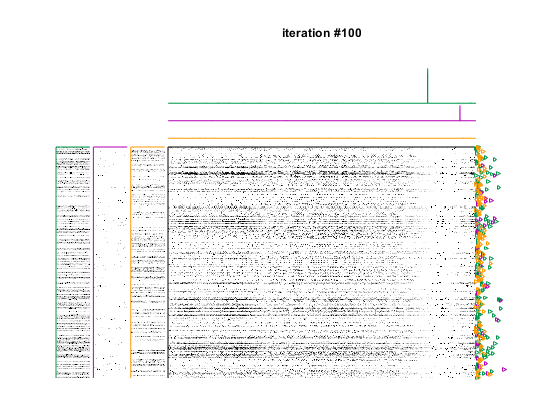

Testing significance of factors on held-out data


Found 1/3 significant factors


Running seqNMF...K = 3  L = 8 sec


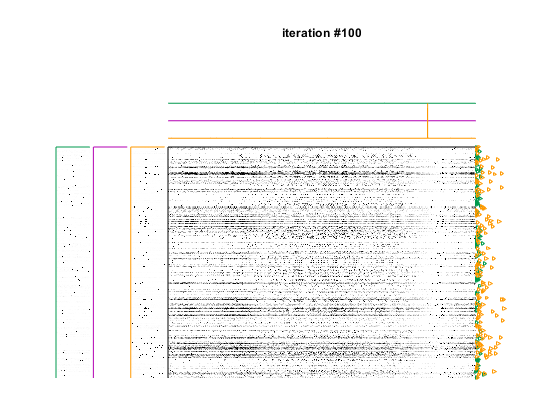

Testing significance of factors on held-out data


Found 1/3 significant factors


Running seqNMF...K = 3  L = 10 sec


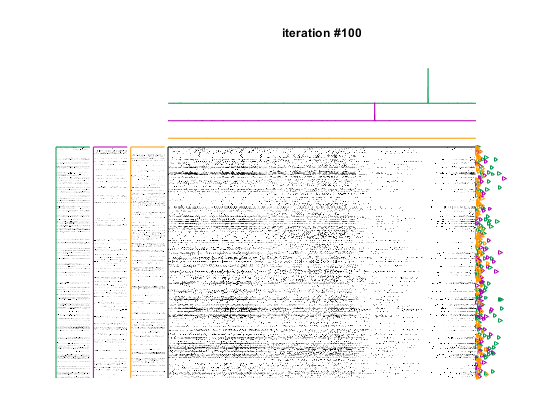

Testing significance of factors on held-out data


Found 2/3 significant factors


Running seqNMF...K = 3  L = 12 sec


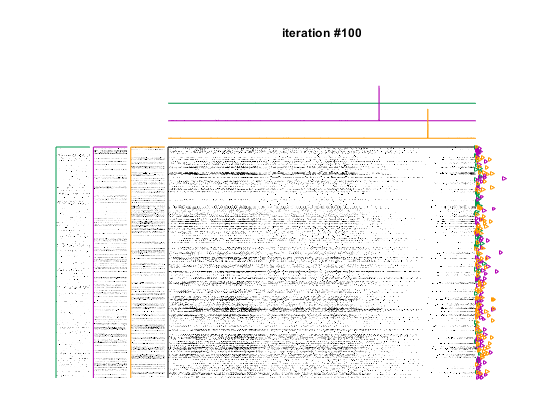

Testing significance of factors on held-out data


Found 2/3 significant factors


Running seqNMF...K = 3  L = 14 sec


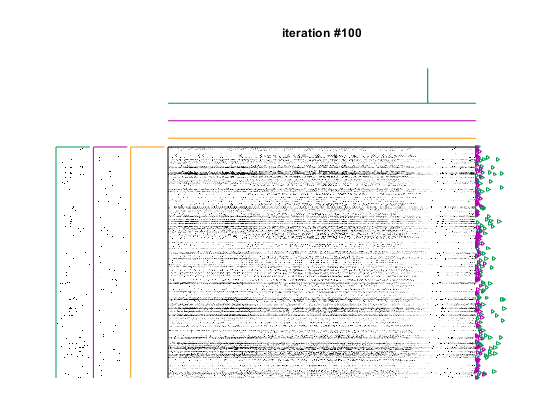

Testing significance of factors on held-out data


Found 1/3 significant factors


Running seqNMF...K = 3  L = 16 sec


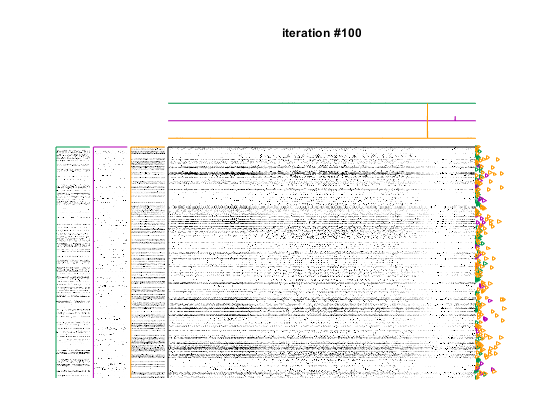

Testing significance of factors on held-out data


Found 1/3 significant factors


Running seqNMF...K = 3  L = 18 sec


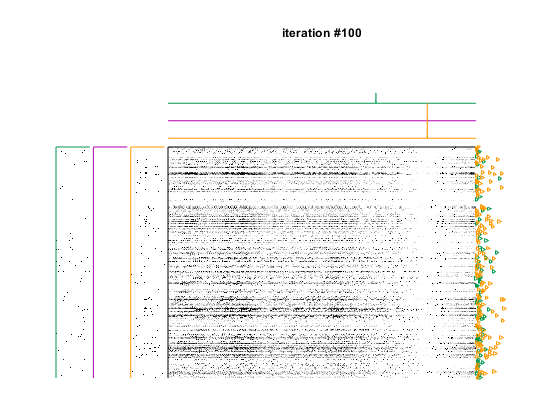

Testing significance of factors on held-out data


Found 0/3 significant factors


Running seqNMF...K = 3  L = 20 sec


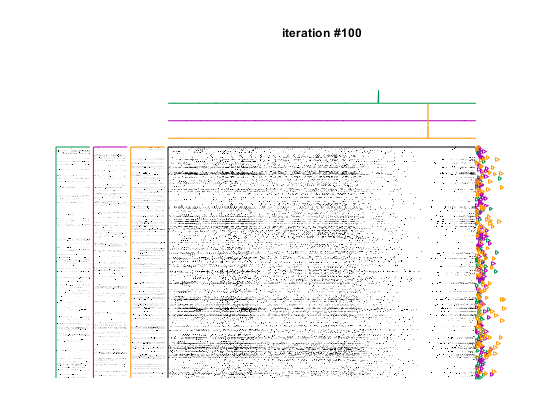

Testing significance of factors on held-out data


Found 1/3 significant factors


% this_REM = circshift(REM_data, floor(length(REM_data)/2),2);
this_REM = REM_data; 
load("LFP_mats\all_t_post_REM.mat");
all_t_post_REM = smooth(all_t_post_REM, Fs)'; 

splitN = floor(size(this_REM,2)*.75);

% make the test/trian sets.
trainNEURAL = this_REM(:,1:splitN);
testNEURAL = this_REM(:,(splitN+1):end);

trainLFP = all_t_post_REM(1:splitN);
testLFP = all_t_post_REM((splitN+1):end);

% Set some parameters
rng(235); % fixed rng seed for reproduceability
X = trainNEURAL;
%events vid
% lambdaOrthoH = .1; % favor events-based (these can take any value, don't need to be zero and one)
% lambdaOrthoW = 0;

%parts based
lambdaOrthoH = 0;
lambdaOrthoW = 1;

Ls = 6:2:20; 

parfor iL = 1:length(Ls)
    fprintf('Running seqNMF...K = %d  L = %d sec\n', K, Ls(iL))
    [W, H, ~,loadings,~]= seqNMF(X,'K',K,'L',ceil(Ls(iL)*Fs),...
        'lambdaL1W', .1, 'lambda', lambda, 'maxiter', 100, 'showPlot', 1,...
        'lambdaOrthoH', lambdaOrthoH, 'lambdaOrthoW', lambdaOrthoW);
    
    % test if any are significant
    p = .05; % desired p value for factors
    
    disp('Testing significance of factors on held-out data')
    [pvals,is_significant] = test_significance(testNEURAL,W,p);
    
    W = W(:,is_significant,:);
    H = H(is_significant,:);
    fprintf('Found %d/%d significant factors\n', sum(is_significant), length(is_significant))
    all_sweeps_parts{iL}.K = K;
    all_sweeps_parts{iL}.L = L;
    all_sweeps_parts{iL}.W = W; 

    all_sweeps_parts{iL}.H = H;
    all_sweeps_parts{iL}.loadings = loadings; 
    all_sweeps_parts{iL}.sig = is_significant;
    all_sweeps_parts{iL}.Train = trainNEURAL;
    all_sweeps_parts{iL}.Trest = testNEURAL;
    
end

Reconstruct a particular L sweep.  

iL = 3; % pick an L to work with
figure;
[max_factor, L_sort, max_sort, hybrid] = helper.ClusterByFactor(all_sweeps_parts{iL}.W(:,:,:),1);

Undefined variable all_sweeps_parts.

indSort = hybrid(:,3);
tstart = 1; % plot data starting at this timebin
WHPlot(all_sweeps_parts{iL}.W(indSort,:,:),all_sweeps_parts{iL}.H(:,tstart:end), all_sweeps_parts{iL}.Train(indSort,tstart:end), ...
    0,trainLFP(:,floor(tstart*Fs/PosFs):end))
title('REM Significant seqNMF factors, with raw data: Parts-based')

figure;
WHPlot(all_sweeps_parts{iL}.W(indSort,:,:),all_sweeps_parts{iL}.H(:,tstart:end), ...
    helper.reconstruct(all_sweeps_parts{iL}.W(indSort,:,:),all_sweeps_parts{iL}.H(:,tstart:end)),...
    0,trainLFP(:,floor(tstart*Fs/PosFs):end))
title('REM SeqNMF reconstruction: Parts-based')

% reconstruct the data using color coded anx and safety cells.

figure;
% offset = 10^-1; % offset for each cell
for iSeq = 1:size(all_sweeps_parts{iL}.W(indSort,:,:),2)
    subplot(size(all_sweeps_parts{iL}.W(indSort,:,:),2),1,iSeq)
    this_seq = squeeze(all_sweeps_parts{iL}.W(indSort,iSeq,:));
    
    imagesc(this_seq);
    
end

ylabel('sorted cell ID')
xlabel('seq frames');
title('Parts-based')

% saveas(gcf,['Seq_Sweeps' filesep 'Sweep_' num2str(L)], 'png')
% clearvars -except all_sweeps trainNEURAL testNEURAL Ls


